# Fitting Sample 2

Steve Turley, March, 2018

This is a record of trying various things to fit sample 2. I'm using LiveScrpt for my documentation.

## Reading Data

clear all
load('log.mat'); % log file
load('runs.mat'); % all runs

% dark currents
dark(8) = mean(runs(98).diode);
dark(9) = mean(runs(99).diode);
dark(10) = mean(runs(100).diode);
dark(7) = mean(runs(101).diode);

% Read in the index of refraction data
global AlIndex Al2O3Index AlF3Index Si3N4Index ...
    SiO2Index
AlIndex = Index('Al');
Al2O3Index = Index('Al2O3');
AlF3Index = Index('AlF3');
Si3N4Index = Index('Si3N4');
SiIndex = Index('Si');
SiO2Index = Index('SiO2');

% all 2t2 with this order-sorter filter
s17a=Reflectance(log, runs, 122, 97, dark);
s17b=Reflectance(log, runs, 125:126, 97, dark);
s17=s17a.filter(0,16) + s17b.filter(16.05, 80);
s18a=Reflectance(log, runs, 119, 97, dark);
s18b=Reflectance(log, runs, 120:121, 97, dark);
s18=s18a.filter(0,18) + s18b.filter(18.05,80);
s20a=Reflectance(log, runs, [127, 131], 97, dark);
s20b=Reflectance(log, runs, 128, 97, dark);
s20=s20a.filter(0, 22) + s20b.filter(22.05, 80);
s22a=Reflectance(log, runs, 132:133, 97, dark);
s22b=Reflectance(log, runs, 134, 97, dark);
s22=s22a.filter(0,23) + s22b.filter(23.05,80);
s24a=Reflectance(log, runs, 135, 97, dark);
s24b=Reflectance(log, runs, 136, 97, dark);
s24=s24a.filter(0, 40) + s24b.filter(40.05,80);
s26=Reflectance(log, runs, 137, 97, dark);
s28=Reflectance(log, runs, 139, 97, dark);
s30a=Reflectance(log, runs, 140, 97, dark);
s30b=Reflectance(log, runs, 141, 97, dark);
s30=s30a.filter(20.05,80) + s30b;

The data isn't good over the entire range, particularly near 0. Graph the plots for each wavelength and determine a good range.

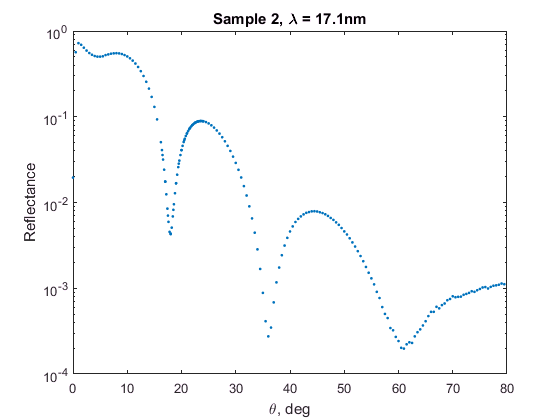

s2plt(s17);

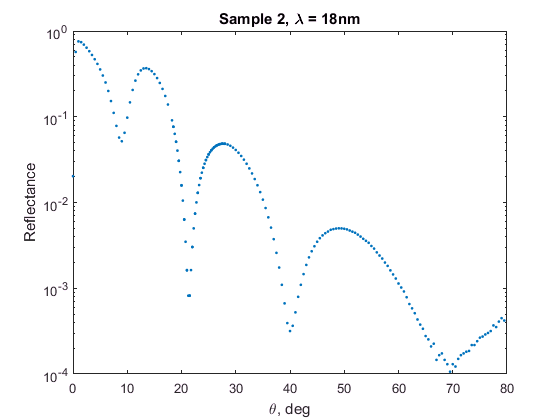

s2plt(s18);

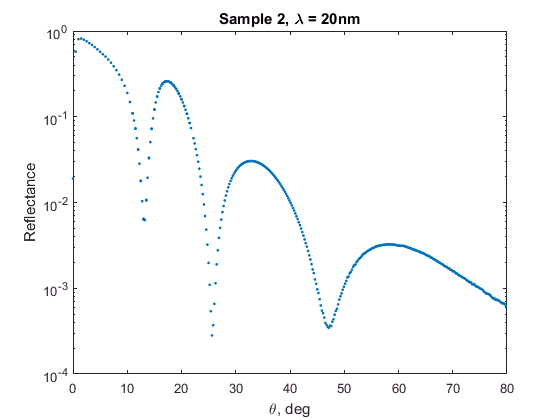

s2plt(s20);

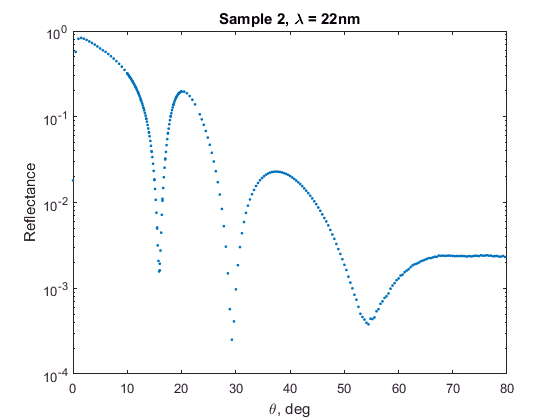

s2plt(s22);

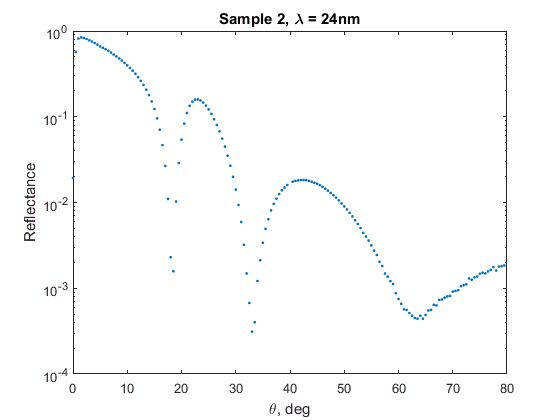

s2plt(s24);

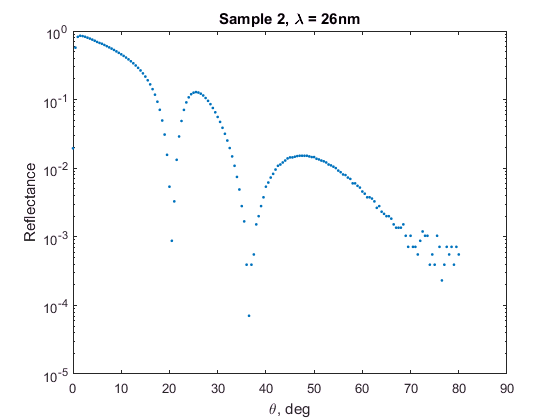

s2plt(s26);

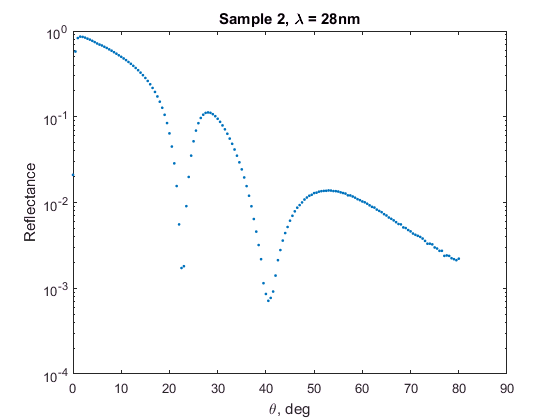

s2plt(s28);

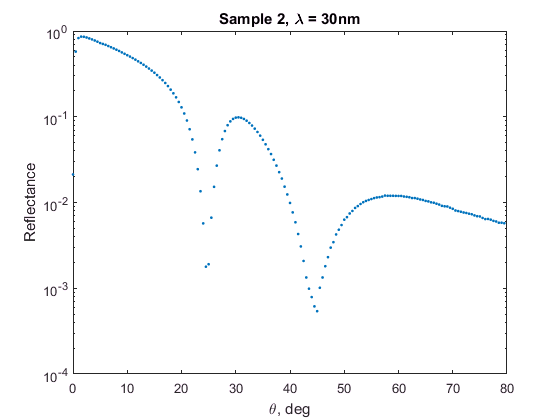

s2plt(s30);

Create filtered spectra with only the good data.

f17=s17.filter(2,80);
f18=s18.filter(2,60);
f20=s20.filter(2,80);
f22=s22.filter(2,80);
f24=s24.filter(2,80);
f26=s26.filter(2,60);
f28=s28.filter(2,80);
f30=s30.filter(2,80);
% We'll skip 30 nm for now. It takes creating a new method
% to put two runs together differently. I'll do that later.

## Fitting

I'll start by fitting these fitting the AlF3 index of refraction and the Al and AlF3 thickness for a start.

b(1)=1.005423 +/- 3.37e-03
b(2)=0.044495 +/- 5.98e-04
b(3)=13.492483 +/- 2.64e-01
b(4)=17.166890 +/- 1.09e-01


b(1)=0.979428 +/- 1.04e-03
b(2)=0.022917 +/- 9.65e-04
b(3)=10.657260 +/- 1.99e-01
b(4)=24.281094 +/- 1.65e-01


b(1)=0.968501 +/- 8.00e-04
b(2)=0.021894 +/- 6.04e-04
b(3)=11.318954 +/- 1.36e-01
b(4)=24.568219 +/- 1.46e-01


b(1)=0.959981 +/- 8.14e-04
b(2)=0.022285 +/- 6.33e-04
b(3)=11.942351 +/- 1.94e-01
b(4)=24.550172 +/- 1.91e-01


b(1)=0.955556 +/- 1.27e-03
b(2)=0.029156 +/- 1.01e-03
b(3)=12.305801 +/- 2.58e-01
b(4)=23.755184 +/- 2.87e-01


b(1)=0.945752 +/- 1.44e-03
b(2)=0.029903 +/- 1.72e-03
b(3)=13.421968 +/- 5.80e-01
b(4)=23.895485 +/- 3.26e-01


b(1)=0.944114 +/- 1.38e-03
b(2)=0.031321 +/- 1.19e-03
b(3)=15.921578 +/- 4.61e-01
b(4)=21.354332 +/- 3.96e-01


b(1)=0.937471 +/- 1.46e-03
b(2)=0.035180 +/- 1.10e-03
b(3)=17.228044 +/- 4.55e-01
b(4)=20.413476 +/- 3.92e-01


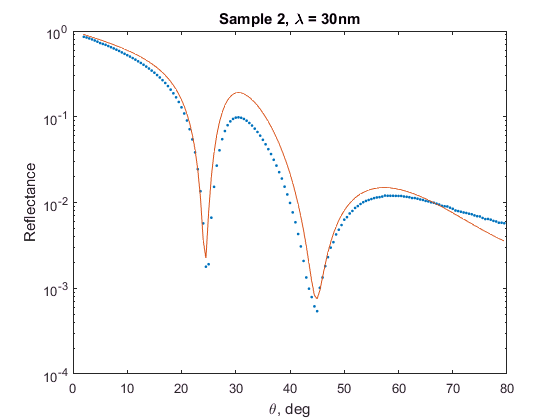

wl = [17.1 18 20 22 24 26 28 30];
sp = [f17 f18 f20 f22 f24 f26 f28 f30];
e = 0;
b = [];
for f = sp
    [b2,e2] = s2fit(f);
    b = [b; b2];
    e = e + e2;
end

fprintf('total error = %f\n',e);

total error = 3.984066


Plot the various fitted quantities to see if there is a trend.

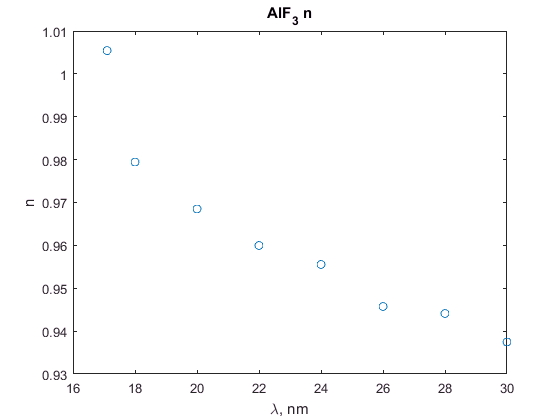

figure
plot(wl,b(:,1),'o');
title('AlF_3 n');
xlabel('\lambda, nm');
ylabel('n');

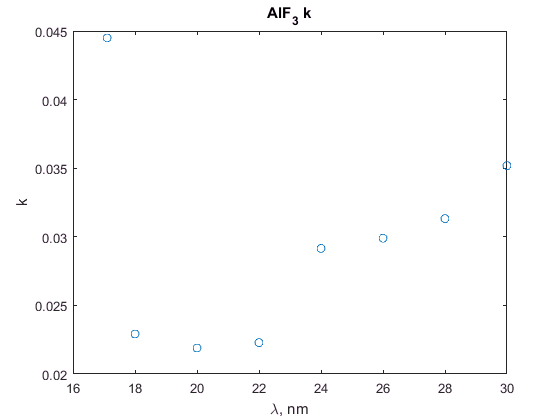

figure
plot(wl,b(:,2),'o');
title('AlF_3 k');
xlabel('\lambda, nm');
ylabel('k');

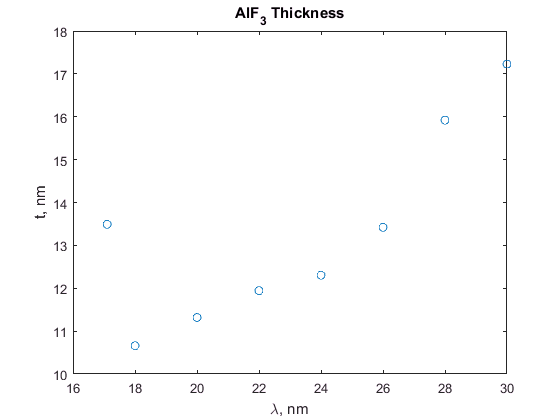

figure
plot(wl,b(:,3),'o');
title('AlF_3 Thickness');
xlabel('\lambda, nm');
ylabel("t, nm");

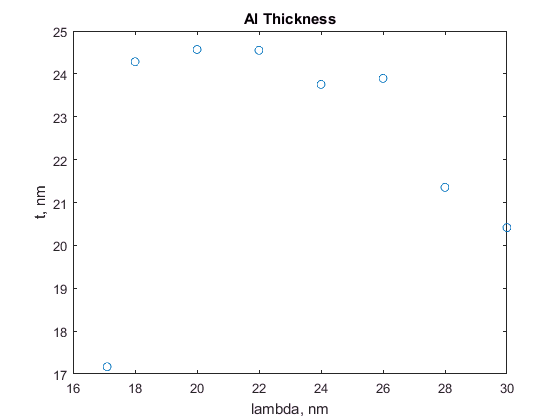

figure
plot(wl,b(:,4),'o');
title('Al Thickness');
xlabel('lambda, nm');
ylabel('t, nm');

The fact that these fits are trying to steadily increase the thickenss of the AlF3 layer tells me that I probably am having trouble with my model. They mostly like the thickness of the Al layer however.

In the following sections I'll check different ways to refine the model and see what makes a difference.

## Si3N4 a Substrate?

In this section I'll check and see if it is important to put a Si substrate with an SiO2 layer on top underneath the Si3N4 layer.

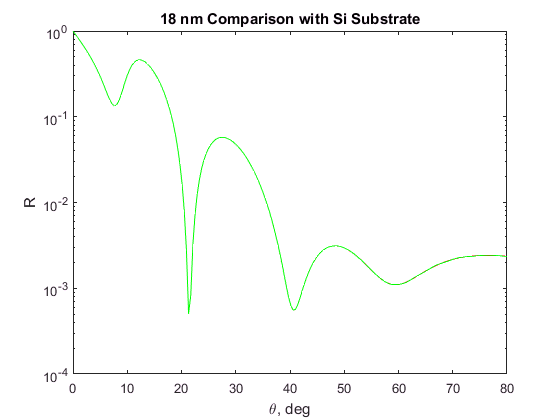

alndx = AlIndex.at(18);
alf3ndx = b(2,1)+b(2,2)*1i;
si3n4ndx = Si3N4Index.at(18);
sio2ndx = SiO2Index.at(18);
sindx = SiIndex.at(18);
n = [1, alf3ndx, alndx, si3n4ndx];
x = [0, 11, 24, 0];
sigma = [0.2,0,0];
angle=linspace(0,80,200);
r1 = zeros(size(angle));
for i=1:length(angle)
    r1(i)=Parratt(n, x, angle(i), f18.fracs, 18, sigma);
end
n = [1 alf3ndx, alndx, si3n4ndx, sio2ndx, sindx];
x = [0, 11, 24, 300, 1.6, 0];
sigma2 = [0.2,0,0,0,0];
r2 = zeros(size(angle));
for i=1:length(angle)
    r2(i)=Parratt(n, x, angle(i), f18.fracs, 18, sigma2);
end
figure
semilogy(angle, r1, 'r', angle, r2, 'g');
title('18 nm Comparison with Si Substrate');
xlabel('\theta, deg');
ylabel('R');

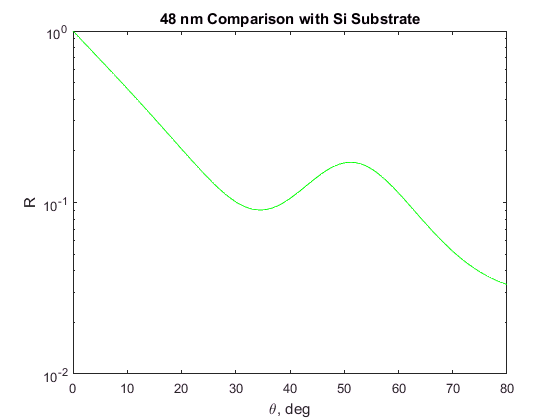


% Repeat at 30 28 48 nm
alndx = AlIndex.at(48);
alf3ndx = AlF3Index.at(48);
si3n4ndx = Si3N4Index.at(48);
sio2ndx = SiO2Index.at(48);
sindx = SiIndex.at(48);
n = [1, alf3ndx, alndx, si3n4ndx];
x = [0, 11, 24, 0];
sigma = [0.2,0,0];
angle=linspace(0,80,200);
r1 = zeros(size(angle));
fracs = polarfind(48);
for i=1:length(angle)
    r1(i)=Parratt(n, x, angle(i), fracs, 48, sigma);
end
n = [1 alf3ndx, alndx, si3n4ndx, sio2ndx, sindx];
x = [0, 11, 24, 300, 1.6, 0];
r2 = zeros(size(angle));
for i=1:length(angle)
    r2(i)=Parratt(n, x, angle(i), fracs, 48, sigma2);
end
figure
semilogy(angle, r1, 'r', angle, r2, 'g');
title('48 nm Comparison with Si Substrate');
xlabel('\theta, deg');
ylabel('R');

I see no difference in the curves at the two test wavelengths. My conclusion is that there is no need to include the Si and SiO2 in the calculations.

## Add an Oxide Layer on the Aluminum

It's possible the aluminum oxidized. Allow an oxide layer in the Aluminum and fit its thickness. This gives me a lot of parameters, so be careful.

Fitting AlF3 index with Al2O3 layer at lambda=17.100000
b(1)=1.006203 +/- 2.72e-03
b(2)=0.045041 +/- 6.36e-04
b(3)=11.632676 +/- 1.21e+00
b(4)=17.821334 +/- 5.76e-01
b(5)=1.214647 +/- 7.41e-01


Fitting AlF3 index with Al2O3 layer at lambda=18.000100
b(1)=1.165255 +/- 3.57e-02
b(2)=0.205516 +/- 2.43e-02
b(3)=0.983531 +/- 1.73e-01
b(4)=22.494655 +/- 1.53e-01
b(5)=5.489777 +/- 1.87e-01


Fitting AlF3 index with Al2O3 layer at lambda=19.999900
b(1)=0.968656 +/- 8.22e-04
b(2)=0.022044 +/- 6.33e-04
b(3)=11.104278 +/- 3.00e+00
b(4)=24.658757 +/- 1.71e+00
b(5)=0.092092 +/- 1.32e+00


Fitting AlF3 index with Al2O3 layer at lambda=22.000100
b(1)=0.959388 +/- 7.44e-04
b(2)=0.021831 +/- 5.58e-04
b(3)=13.416055 +/- 6.50e-01
b(4)=23.757087 +/- 4.01e-01
b(5)=-0.523821 +/- 2.16e-01


Fitting AlF3 index with Al2O3 layer at lambda=23.999900
b(1)=0.957719 +/- 1.32e-03
b(2)=0.028008 +/- 1.96e-03
b(3)=9.950893 +/- 3.20e-01
b(4)=25.425209 +/- 3.77e-01
b(5)=0.992344 +/- 1.72e-01


Fitting AlF3 index with Al2O3 layer at lambda=26.000100
b(1)=0.945527 +/- 3.35e-03
b(2)=0.029481 +/- 3.07e-03
b(3)=14.278541 +/- 1.36e+01
b(4)=23.351027 +/- 9.57e+00
b(5)=-0.222743 +/- 3.51e+00


Fitting AlF3 index with Al2O3 layer at lambda=27.999900
b(1)=0.948878 +/- 1.89e-03
b(2)=0.032130 +/- 2.34e-03
b(3)=12.507078 +/- 5.76e-01
b(4)=23.631398 +/- 5.25e-01
b(5)=1.042691 +/- 2.53e-01


Fitting AlF3 index with Al2O3 layer at lambda=30.000100
b(1)=0.941835 +/- 3.26e-03
b(2)=0.037629 +/- 2.73e-03
b(3)=13.797548 +/- 2.48e+00
b(4)=22.655521 +/- 2.13e+00
b(5)=0.839873 +/- 7.76e-01


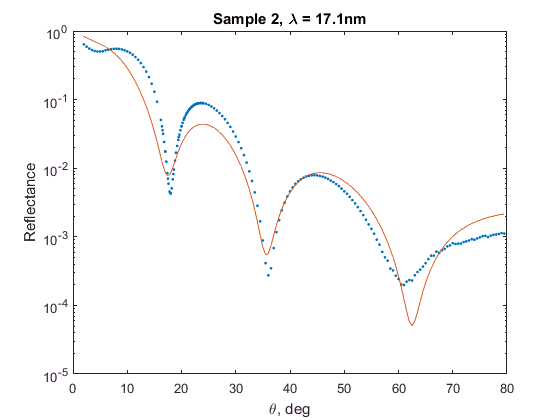

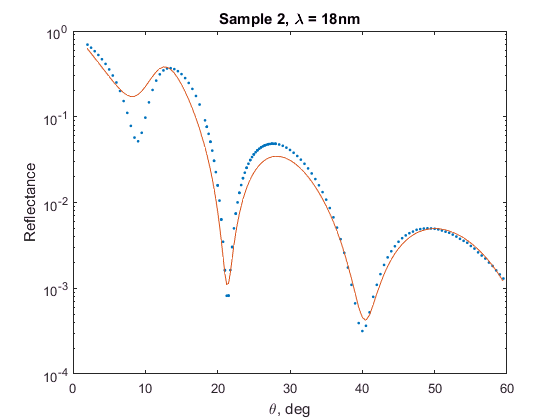

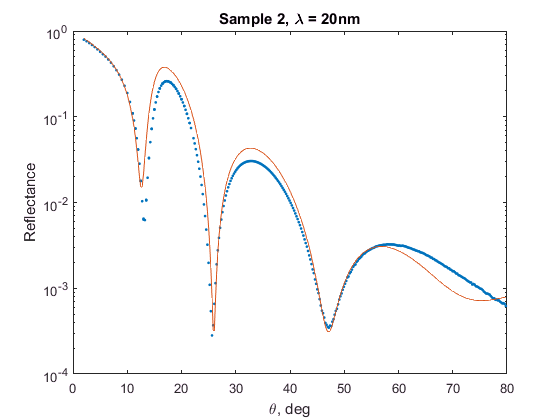

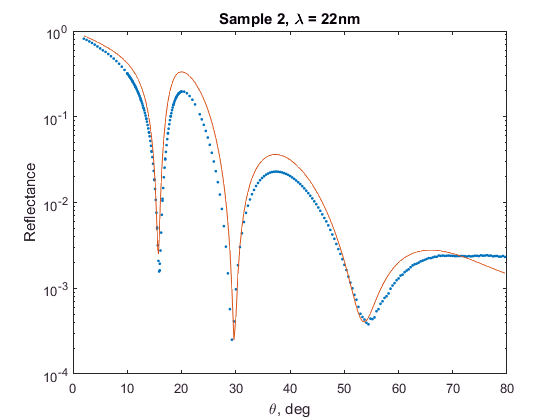

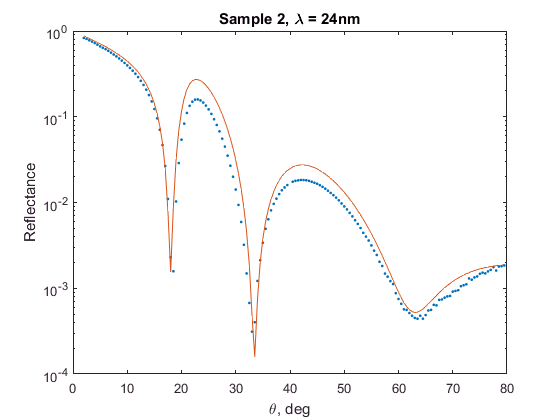

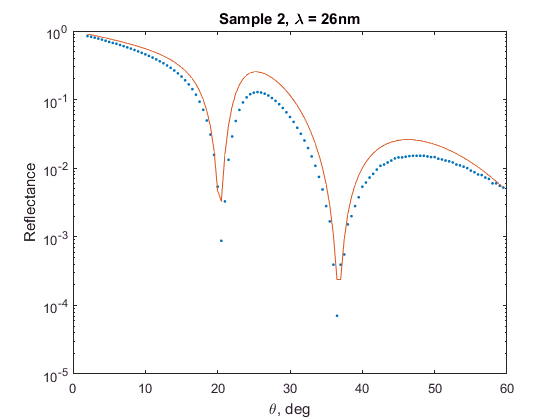

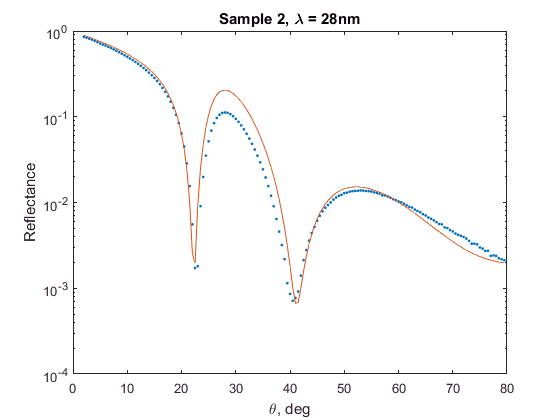

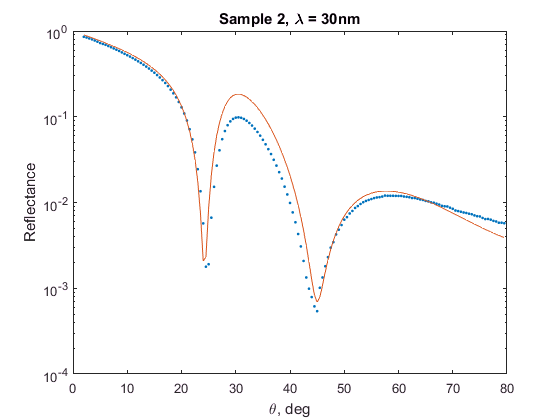

e = 0;
b = [];
for f = sp
    [b2,e2] = s2fita(f);
    b = [b; b2];
    e = e + e2;
end

fprintf('total error = %f\n',e);

total error = 3.741525


Plot the various fitted quantities to see if there is a trend.

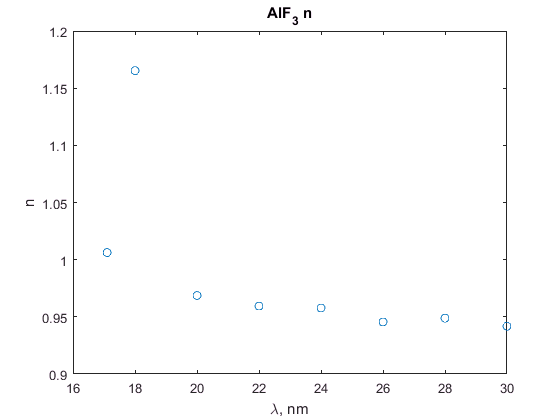

figure
plot(wl,b(:,1),'o');
title('AlF_3 n');
xlabel('\lambda, nm');
ylabel('n');

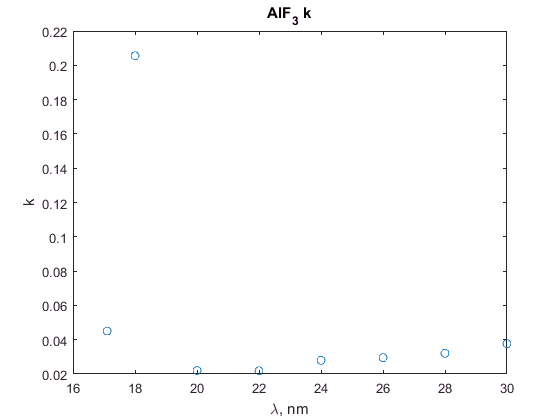

figure
plot(wl,b(:,2),'o');
title('AlF_3 k');
xlabel('\lambda, nm');
ylabel('k');

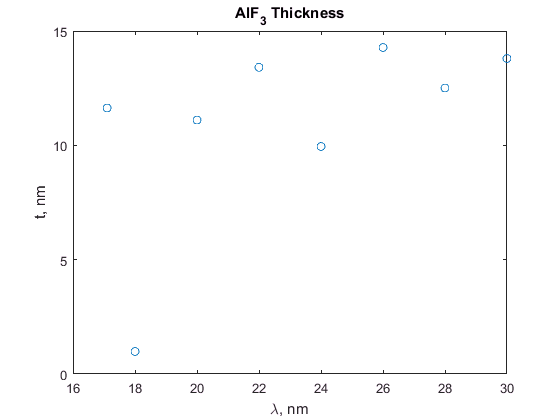

figure
plot(wl,b(:,3),'o');
title('AlF_3 Thickness');
xlabel('\lambda, nm');
ylabel("t, nm");

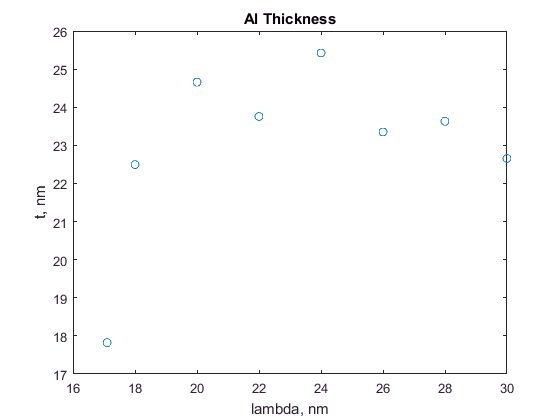

figure
plot(wl,b(:,4),'o');
title('Al Thickness');
xlabel('lambda, nm');
ylabel('t, nm');

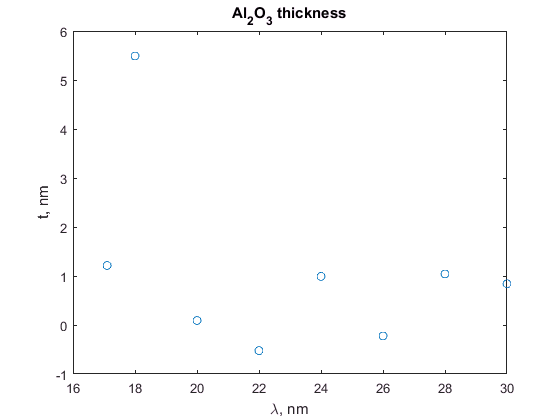

figure
plot(wl,b(:,5),'o');
title('Al_2O_3 thickness');
xlabel('\lambda, nm');
ylabel('t, nm');

There is something odd with the fit at 18 nm that will take some adjustment. What I like about these fits is that that Al2O3 thickness is pretty consistent across wavelengths and the Al2F3 thickness is pretty constant across wavelengths as well. Given that improvement, the total mean square error didn't change by much..

## Fit Aluminum Index

This allows for entire oxidation or just bad aluminum with some sort of homogeneous index of refraction.

Fitting AlF3 and Al index and thickness at lambda=17.100000
b(1)=0.978368 +/- 2.60e-04
b(2)=0.013054 +/- 2.46e-03
b(3)=7.842085 +/- 5.72e-02
b(4)=1.020443 +/- 2.87e-04
b(5)=0.012535 +/- 6.02e-04
b(6)=27.364508 +/- 1.79e-01


Fitting AlF3 and Al index and thickness at lambda=18.000100
b(1)=0.986311 +/- 8.26e-04
b(2)=0.036796 +/- 5.33e-04
b(3)=9.306845 +/- 7.39e-02
b(4)=0.998343 +/- 5.26e-04
b(5)=0.002164 +/- 3.50e-04
b(6)=24.813008 +/- 8.18e-02


Fitting AlF3 and Al index and thickness at lambda=19.999900
b(1)=0.977934 +/- 5.03e-04
b(2)=0.030889 +/- 4.35e-04
b(3)=9.943743 +/- 6.94e-02
b(4)=0.989049 +/- 2.91e-04
b(5)=0.003256 +/- 2.38e-04
b(6)=24.712363 +/- 7.34e-02


Fitting AlF3 and Al index and thickness at lambda=22.000100
b(1)=0.971881 +/- 3.98e-04
b(2)=0.030864 +/- 3.80e-04
b(3)=12.207952 +/- 1.11e-01
b(4)=0.979825 +/- 2.52e-04
b(5)=0.002834 +/- 2.73e-04
b(6)=23.515217 +/- 1.09e-01


Fitting AlF3 and Al index and thickness at lambda=23.999900
b(1)=0.976064 +/- 6.92e-04
b(2)=0.033541 +/- 5.12e-04
b(3)=14.184366 +/- 1.44e-01
b(4)=0.961325 +/- 9.42e-04
b(5)=0.003238 +/- 5.10e-04
b(6)=21.562902 +/- 1.29e-01


Fitting AlF3 and Al index and thickness at lambda=26.000100
b(1)=0.964492 +/- 6.87e-04
b(2)=0.038648 +/- 5.93e-04
b(3)=13.936146 +/- 4.16e-01
b(4)=0.957987 +/- 7.66e-04
b(5)=0.008330 +/- 6.83e-04
b(6)=22.058792 +/- 2.86e-01


Fitting AlF3 and Al index and thickness at lambda=27.999900
b(1)=0.965086 +/- 6.77e-04
b(2)=0.017587 +/- 1.80e-03
b(3)=29.617542 +/- 7.66e+00
b(4)=1.070392 +/- 6.03e-01
b(5)=0.080138 +/- 1.74e-01
b(6)=2.862538 +/- 1.24e+01


Fitting AlF3 and Al index and thickness at lambda=30.000100
b(1)=0.954428 +/- 8.79e-04
b(2)=0.053321 +/- 8.91e-04
b(3)=15.358590 +/- 2.52e-01
b(4)=0.930987 +/- 1.30e-03
b(5)=0.013384 +/- 8.53e-04
b(6)=20.903392 +/- 1.63e-01


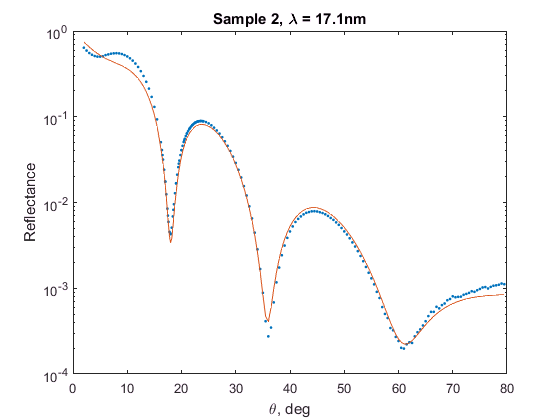

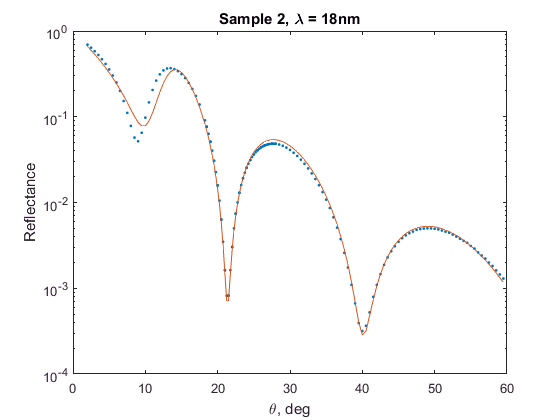

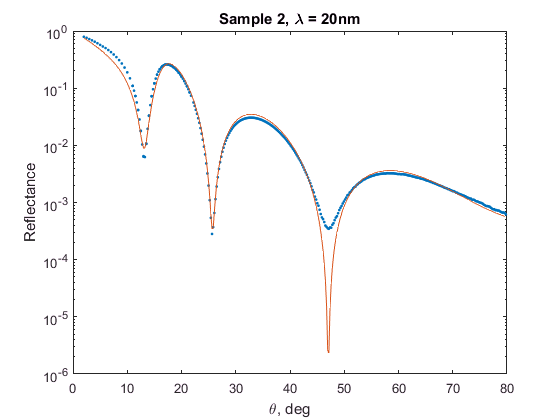

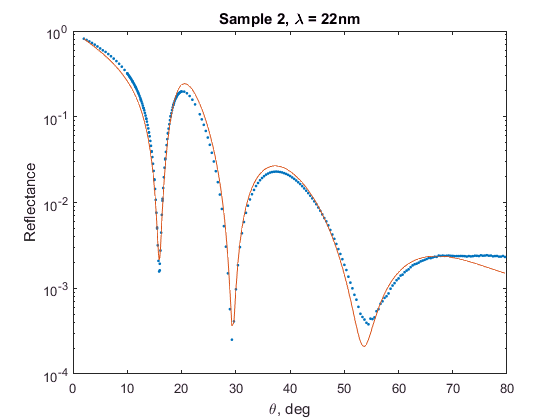

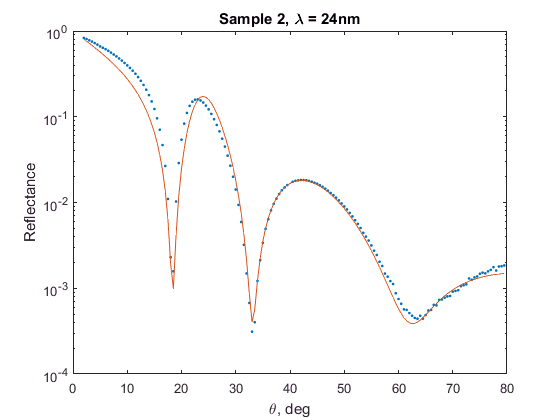

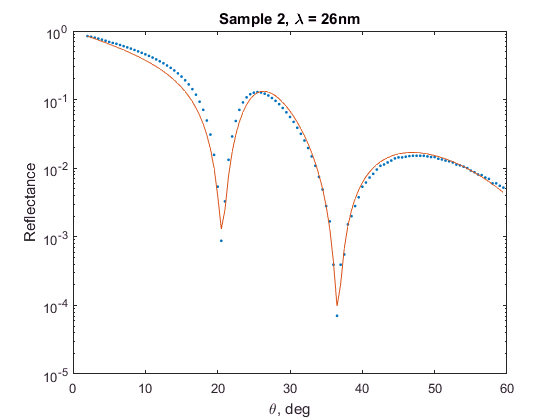

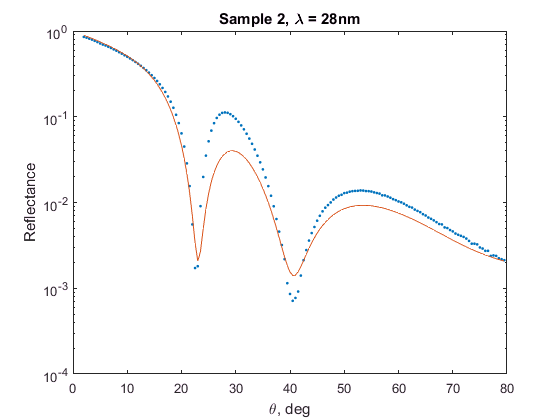

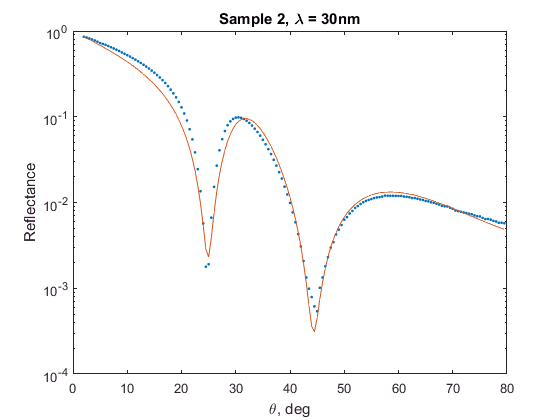

e = 0;
b = [];
for f = sp
    [b2,e2] = s2fitb(f);
    b = [b; b2];
    e = e + e2;
end

% Save these values for later
bfall = b;
fprintf('total error = %f\n',e);

total error = 0.416146


This fits are significantly better than any of the previous ones. The question is whether fitting the Al index of refraction of a meaningful thing to do. Does it reflect the real material, is it just an extra parameter, is it some sort of effective medium approximation or something else?

One intersting insight would be looking at the fit parameters. Does the aparent index of he Al (or Al2O3) layer tell us something about the index of refraction. First let's look at the other parameters.

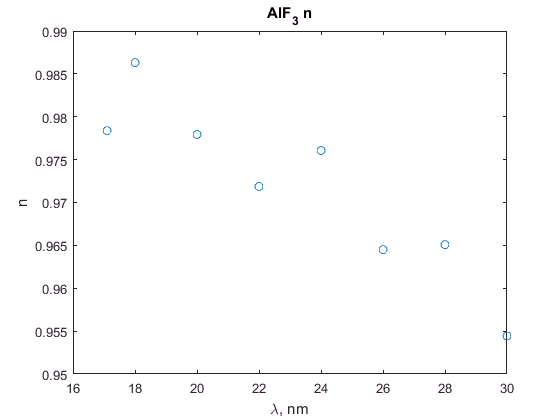

figure
plot(wl,b(:,1),'o');
title('AlF_3 n');
xlabel('\lambda, nm');
ylabel('n');

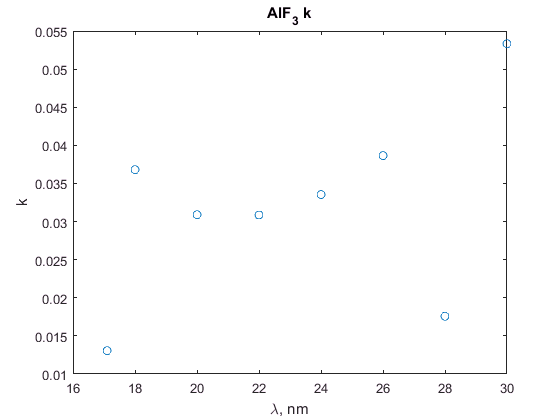

figure
plot(wl,b(:,2),'o');
title('AlF_3 k');
xlabel('\lambda, nm');
ylabel('k');

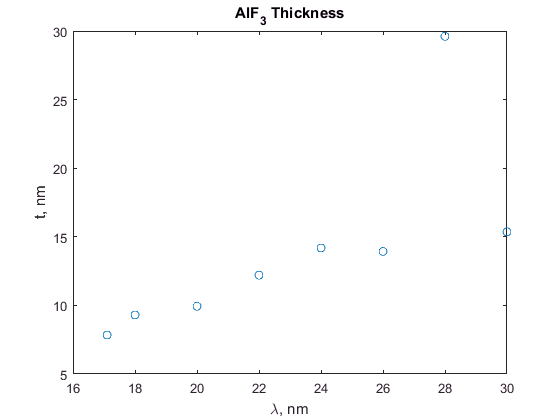

figure
plot(wl,b(:,3),'o');
title('AlF_3 Thickness');
xlabel('\lambda, nm');
ylabel("t, nm");

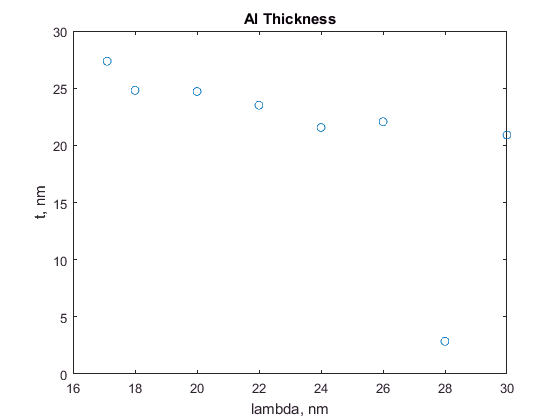

figure
plot(wl,b(:,6),'o');
title('Al Thickness');
xlabel('lambda, nm');
ylabel('t, nm');

The consistency of the AlF3 thickness isn't as good as when we had a straight AlO2 layer on top of Al.. The Al thickness is about the same in both cases. Let's look at the index of the Al compared to Al and Al2O3 from the tables.

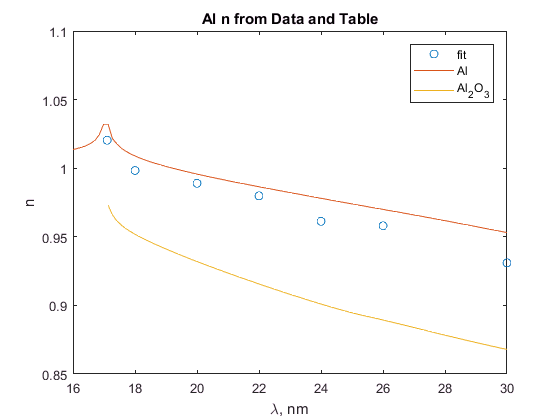

lambda=linspace(16,30);
alndx=AlIndex.at(lambda);
al2o3ndx=Al2O3Index.at(lambda);
figure
plot(wl,b(:,4),'o',lambda,real(alndx),'-',...
    lambda,real(al2o3ndx),'-');
title('Al n from Data and Table');
xlabel('\lambda, nm');
ylabel('n');
legend('fit','Al','Al_2O_3');

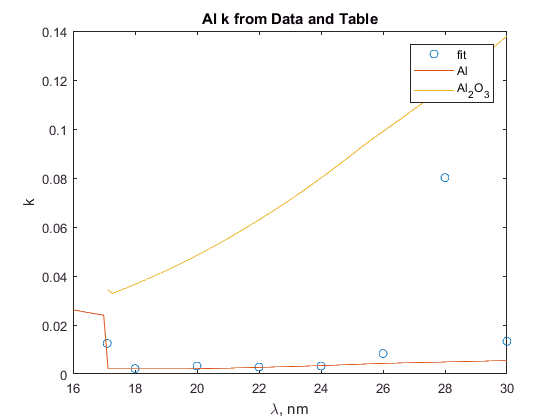

figure
plot(wl,b(:,5),'o',lambda, imag(alndx), '-',...
    lambda,imag(al2o3ndx),'-');
title('Al k from Data and Table');
xlabel('\lambda, nm');
ylabel('k');
legend('fit','Al','Al_2O_3');

Interesting! Even though the fit to the data is a lot better fitting the Al index of refraction, the material looks a lot more like the aluminum index in the CXRO tables than like Al$_2$O$_3$. That's good news. Secondly, fitting the index reproduces the bump I would expect to see near the Al edge at 17.1 nm. 

## Lessons Learned

The underlaying layer is mostly Al. There is some indication that I might have a thin oxide layer on top, but the evidence isn't very strong. If it is there, it is about 1 nm thick. Fitting the index near the Al edge at 17.1 nm is tricky, as I would expect. So far, it looks like the Al thickness is about 23 nm and the AlF$_3$ thickness is about 12.5 nm.

## Constant Layer Thickness

In this section, I'll refit the data with a constant layer thickness. I won't put in the Al2O3 layer. Then I'll compare the fitted index values to the tabulated ones.

Fitting AlF3 and Al index lambda=17.100000
b(1)=1.003527 +/- 1.16e-03
b(2)=-0.001024 +/- 5.33e-04
b(3)=0.977626 +/- 7.41e-04
b(4)=0.013982 +/- 4.51e-04


Fitting AlF3 and Al index lambda=18.000100
b(1)=0.985706 +/- 1.13e-03
b(2)=0.051124 +/- 8.46e-04
b(3)=0.992144 +/- 1.01e-03
b(4)=-0.017942 +/- 3.90e-04


Fitting AlF3 and Al index lambda=19.999900
b(1)=0.979833 +/- 4.55e-04
b(2)=0.029669 +/- 4.56e-04
b(3)=0.988250 +/- 4.33e-04
b(4)=0.000046 +/- 3.53e-04


Fitting AlF3 and Al index lambda=22.000100
b(1)=0.973755 +/- 2.84e-04
b(2)=0.031892 +/- 3.61e-04
b(3)=0.979031 +/- 2.26e-04
b(4)=0.002432 +/- 2.50e-04


Fitting AlF3 and Al index lambda=23.999900
b(1)=0.967992 +/- 3.89e-04
b(2)=0.033089 +/- 4.74e-04
b(3)=0.971186 +/- 3.62e-04
b(4)=0.006774 +/- 3.92e-04


Fitting AlF3 and Al index lambda=26.000100
b(1)=0.963881 +/- 4.34e-04
b(2)=0.040328 +/- 4.05e-04
b(3)=0.959432 +/- 5.72e-04
b(4)=0.009861 +/- 3.94e-04


Fitting AlF3 and Al index lambda=27.999900
b(1)=0.955758 +/- 4.00e-04
b(2)=0.037357 +/- 5.79e-04
b(3)=0.955861 +/- 4.48e-04
b(4)=0.014775 +/- 3.82e-04


Fitting AlF3 and Al index lambda=30.000100
b(1)=0.951364 +/- 3.41e-04
b(2)=0.039622 +/- 4.23e-04
b(3)=0.948497 +/- 3.90e-04
b(4)=0.020804 +/- 3.33e-04


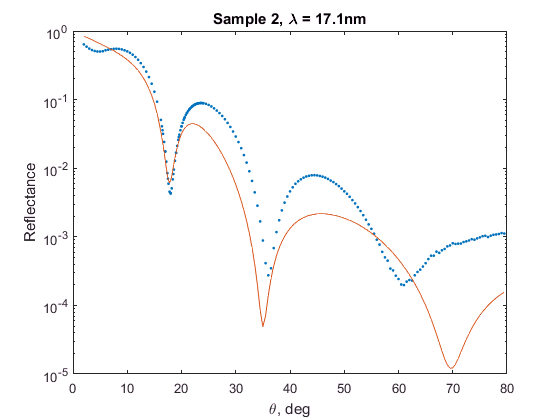

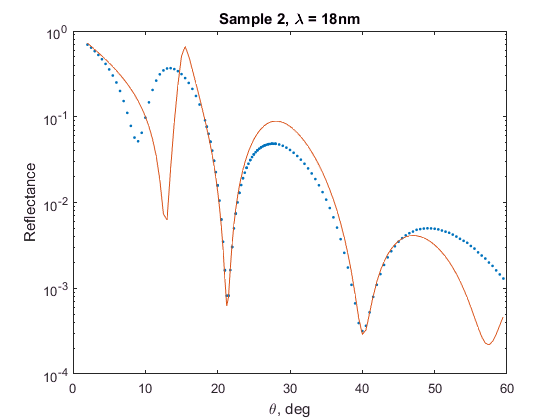

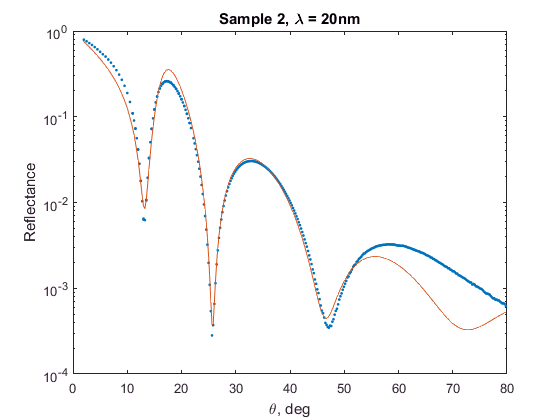

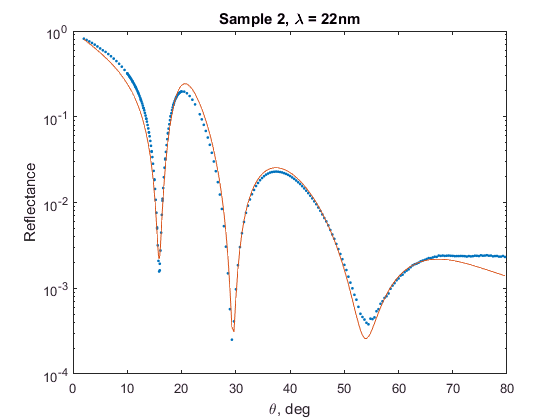

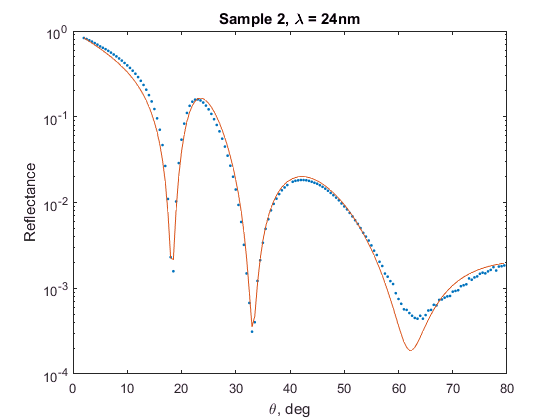

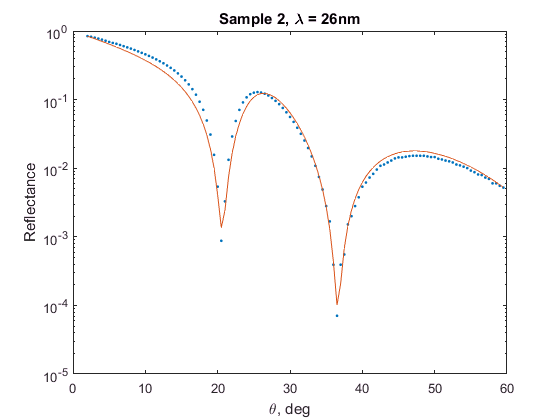

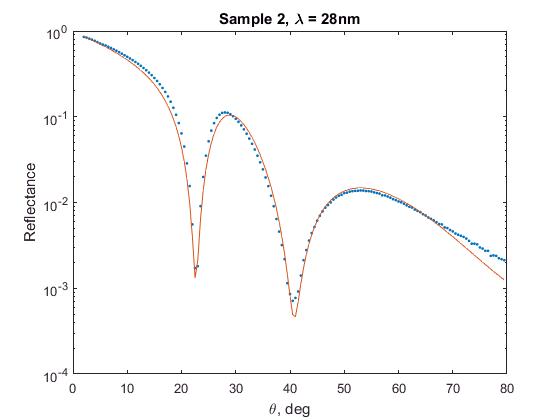

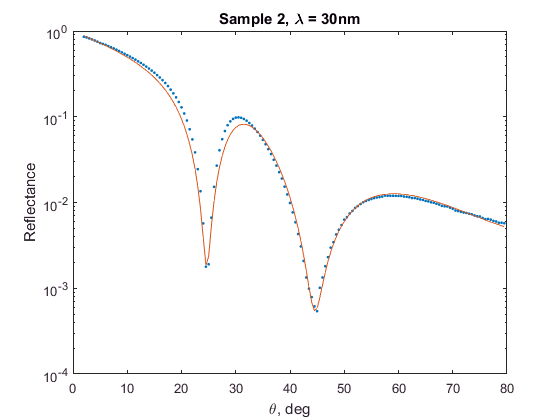

e = 0;
b = [];
for f = sp
    [b2,e2] = s2fitc(f);
    b = [b; b2];
    e = e + e2;
end

fprintf('total error = %f\n',e);

total error = 1.105225


This doesn't look so good at the shortest wavelengths and the fit is about 3 times worse as measured by the total mean square error. Is the problem not fitting the thickness at the shortest wavelengths or starting with the Al optical constants in the fit instead of the Al2O3 optical constants? Let's try again starting with the Al2O3 optical constants as the initial guess.

Fitting AlF3 and Al index lambda=17.100000
b(1)=1.003527 +/- 1.16e-03
b(2)=-0.001024 +/- 5.33e-04
b(3)=0.977626 +/- 7.41e-04
b(4)=0.013982 +/- 4.51e-04


Fitting AlF3 and Al index lambda=18.000100
b(1)=1.007679 +/- 7.40e-04
b(2)=0.009002 +/- 4.63e-04
b(3)=0.968690 +/- 3.37e-04
b(4)=0.007338 +/- 4.11e-04


Fitting AlF3 and Al index lambda=19.999900
b(1)=1.000985 +/- 7.26e-04
b(2)=0.024317 +/- 4.09e-04
b(3)=0.960376 +/- 5.39e-04
b(4)=0.003848 +/- 4.82e-04


Fitting AlF3 and Al index lambda=22.000100
b(1)=0.973755 +/- 2.84e-04
b(2)=0.031892 +/- 3.61e-04
b(3)=0.979030 +/- 2.26e-04
b(4)=0.002431 +/- 2.50e-04


Fitting AlF3 and Al index lambda=23.999900
b(1)=0.967992 +/- 3.89e-04
b(2)=0.033089 +/- 4.74e-04
b(3)=0.971186 +/- 3.62e-04
b(4)=0.006774 +/- 3.92e-04


Fitting AlF3 and Al index lambda=26.000100
b(1)=0.993714 +/- 2.25e-02
b(2)=0.047193 +/- 9.65e-02
b(3)=0.954518 +/- 1.58e-02
b(4)=0.121590 +/- 1.43e-01


Fitting AlF3 and Al index lambda=27.999900
b(1)=0.955758 +/- 4.00e-04
b(2)=0.037357 +/- 5.79e-04
b(3)=0.955861 +/- 4.48e-04
b(4)=0.014775 +/- 3.82e-04


Fitting AlF3 and Al index lambda=30.000100
b(1)=0.951364 +/- 3.41e-04
b(2)=0.039622 +/- 4.23e-04
b(3)=0.948497 +/- 3.90e-04
b(4)=0.020804 +/- 3.33e-04


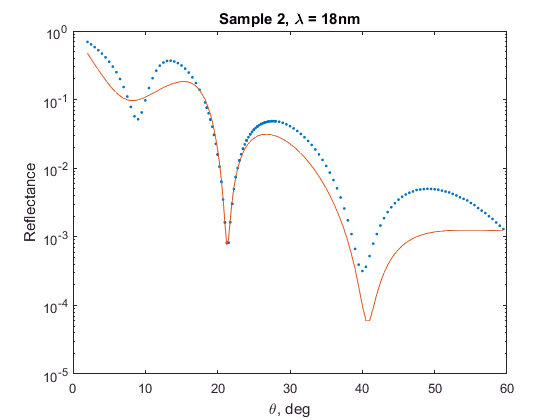

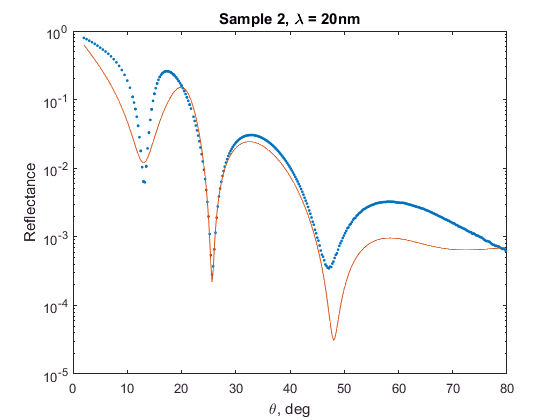

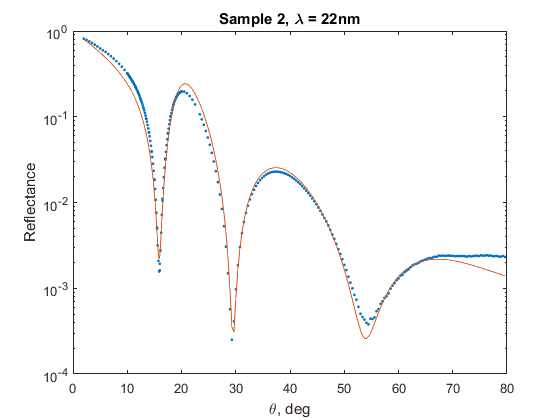

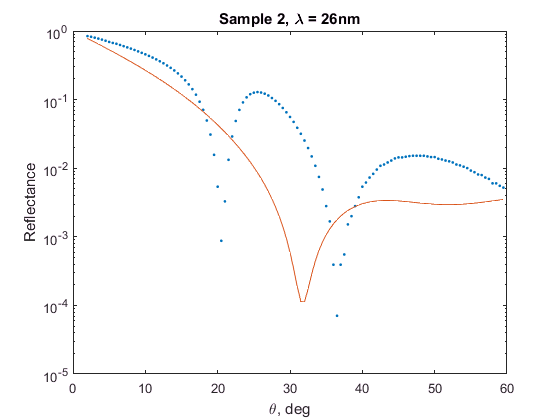

e = 0;
b = [];
for f = sp
    [b2,e2] = s2fitd(f);
    b = [b; b2];
    e = e + e2;
end

fprintf('total error = %f\n',e);

total error = 24.270673


Ugh! That's a lot worse. Let's try starting with initial values from the fits where I fit the thickness as well from above.

Fitting AlF3 and Al index lambda=17.100000
b(1)=1.003527 +/- 1.16e-03
b(2)=-0.001024 +/- 5.33e-04
b(3)=0.977626 +/- 7.41e-04
b(4)=0.013982 +/- 4.51e-04


Fitting AlF3 and Al index lambda=18.000100
b(1)=0.985706 +/- 1.12e-03
b(2)=0.051125 +/- 8.46e-04
b(3)=0.992144 +/- 1.00e-03
b(4)=-0.017943 +/- 3.90e-04


Fitting AlF3 and Al index lambda=19.999900
b(1)=0.978701 +/- 9.37e-04
b(2)=0.056833 +/- 9.71e-04
b(3)=0.983197 +/- 8.37e-04
b(4)=-0.023929 +/- 3.98e-04


Fitting AlF3 and Al index lambda=22.000100
b(1)=0.973755 +/- 2.84e-04
b(2)=0.031893 +/- 3.61e-04
b(3)=0.979030 +/- 2.26e-04
b(4)=0.002431 +/- 2.50e-04


Fitting AlF3 and Al index lambda=23.999900
b(1)=0.967992 +/- 3.89e-04
b(2)=0.033089 +/- 4.73e-04
b(3)=0.971186 +/- 3.62e-04
b(4)=0.006774 +/- 3.92e-04


Fitting AlF3 and Al index lambda=26.000100
b(1)=0.963880 +/- 4.34e-04
b(2)=0.040327 +/- 4.04e-04
b(3)=0.959432 +/- 5.72e-04
b(4)=0.009862 +/- 3.94e-04


Fitting AlF3 and Al index lambda=27.999900
b(1)=1.026283 +/- 1.27e-02
b(2)=0.038129 +/- 2.53e-02
b(3)=1.050401 +/- 3.20e-02
b(4)=0.113751 +/- 2.20e-02


Fitting AlF3 and Al index lambda=30.000100
b(1)=0.951364 +/- 3.41e-04
b(2)=0.039622 +/- 4.23e-04
b(3)=0.948497 +/- 3.90e-04
b(4)=0.020804 +/- 3.33e-04


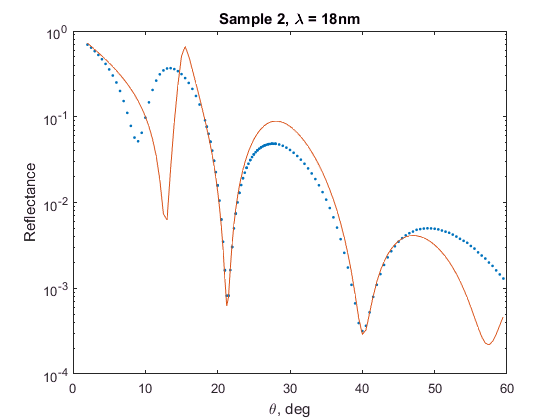

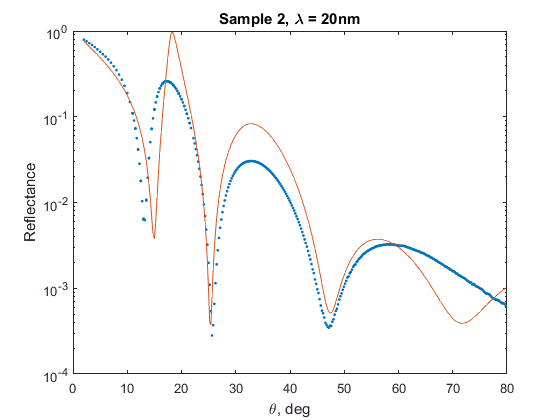

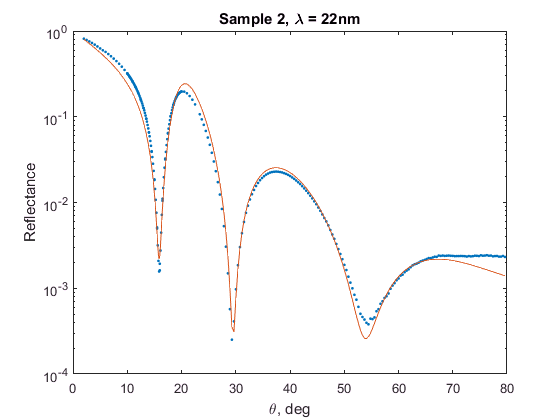

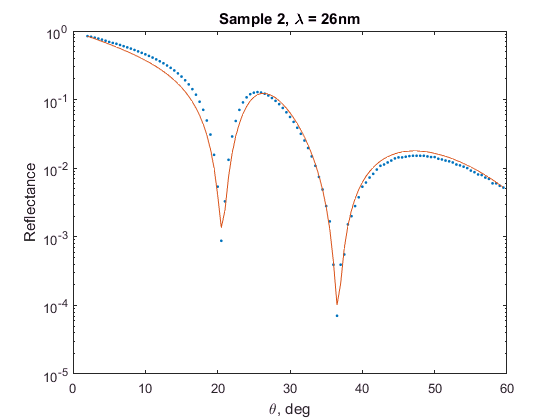

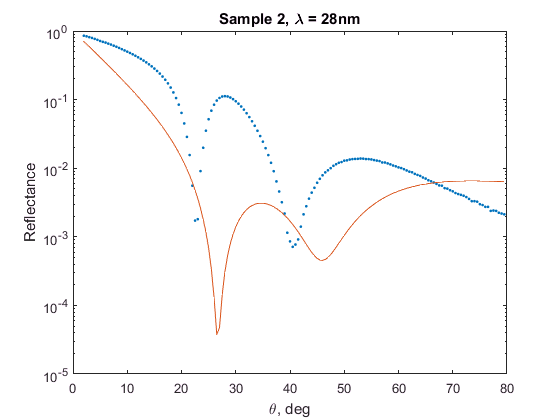

e = 0;
b = [];
i=1;
for f = sp
    [b2,e2] = s2fite(f,bfall(i,4),bfall(i,5));
    b = [b; b2];
    e = e + e2;
    i = i + 1;
end

fprintf('total error = %f\n',e);

total error = 3.171524


The moral is that the fits are significantly better if I can fudge the thickness at each wavelength. There is something important about the model that isn't quite right yet.

## Compare AlF3 index to Table Values

Let's use the values from the older fit and compare to the table values for AlF3.

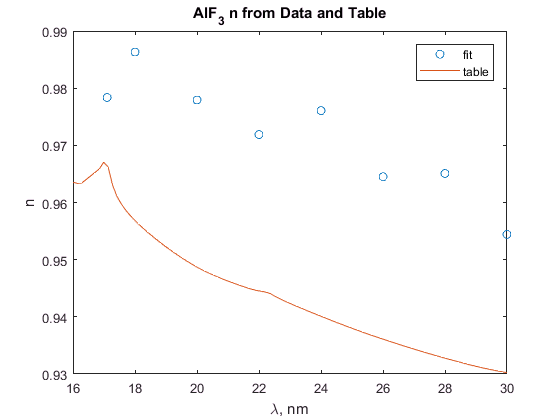

alf3ndx=AlF3Index.at(lambda);
figure
plot(wl,bfall(:,1),'o',lambda,real(alf3ndx),'-');
title('AlF_3 n from Data and Table');
xlabel('\lambda, nm');
ylabel('n');
legend('fit','table');

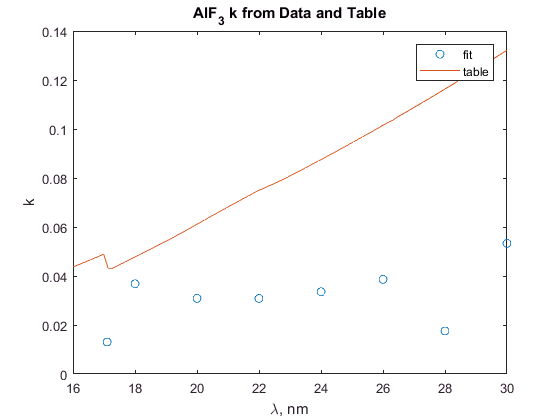

figure
plot(wl,bfall(:,2),'o',lambda, imag(alf3ndx), '-');
title('AlF_3 k from Data and Table');
xlabel('\lambda, nm');
ylabel('k');
legend('fit','table');

**Lesson learned**: So far, the fit data is very different from the table. It would be good to discuss whether we think the table values are that far off, if you have different roughness, if the fluoride might have oxidized, giving us a different material, or if I have a double layer on top (accounting for why I need to fit the thickness as well as the index of refraction to match the data well).

## SiO2 Layer On Top of Si3N4 Substrate

The next thing to try is putting a SiO2 layer on top of the Si3N4 substrate. Allred reports that the nitride can oxidize and this produced better fits in the ellipsometry data. I'll put this off until we have additional discussions.

## Additional Wavelengths

In this section we'll expand the fit to include the longer wavelengths from the next order sorter filter setting.